I1 = imread('Images/cat.jpg');
I2 = imread('Images/dog.jpg');
I3 = imread('cameraman.tif');

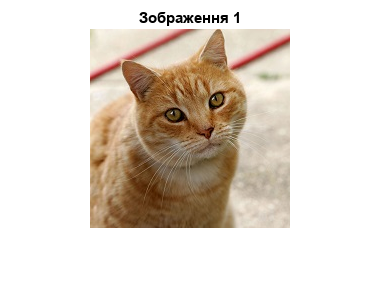

imshow(I1);  
title('Зображення 1');

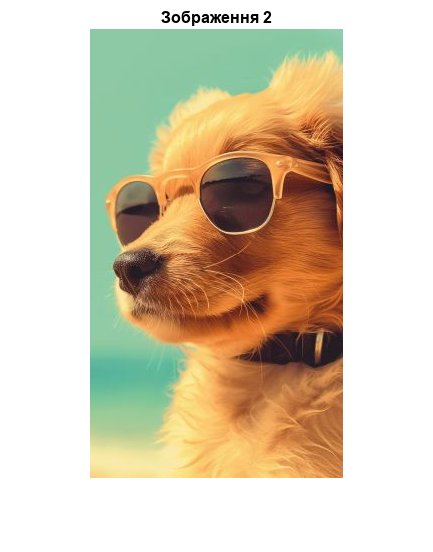

imshow(I2); 
title('Зображення 2');

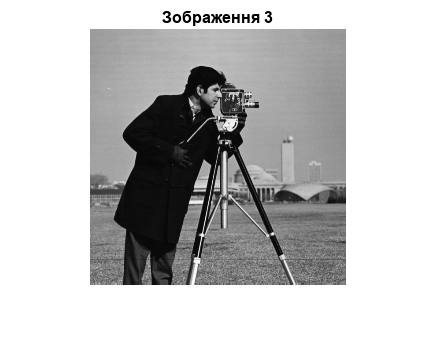

imshow(I3); 
title('Зображення 3');

I1_gray = rgb2gray(I1)

I1_gray = 199×200 uint8 matrix
   206   211   216   221   225   231   237   240   240   240   240   240   240   241   239   237   238   237   237   237   236   236   238   241   241   241   240   240   240   241   241   242   244   243   242   242   241   240   239   238   236   235   234   234   235   236   235   234   232   232
   208   212   217   221   226   232   237   239   241   241   241   240   241   241   239   237   236   236   237   238   237   237   238   240   240   240   239   238   239   239   240   240   242   241   240   239   239   238   237   237   236   235   234   234   234   234   233   232   231   231
   207   211   216   221   227   232   237   238   243   243   242   242   241   241   240   238   236   237   238   239   238   237   238   239   239   238   237   237   237   237   238   238   240   239   238   237   237   236   236   235   235   234   233   233   232   232   231   230   230   229
   204   209   215   220   225   231   235   238   243   244   243

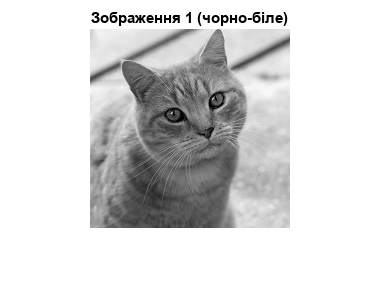

imshow(I1_gray); 
title('Зображення 1 (чорно-біле)');

I2_gray = rgb2gray(I2)

I2_gray = 450×253 uint8 matrix
   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179
   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179
   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179   179
   179   179   179   179   179   179   179   179   179   179   179

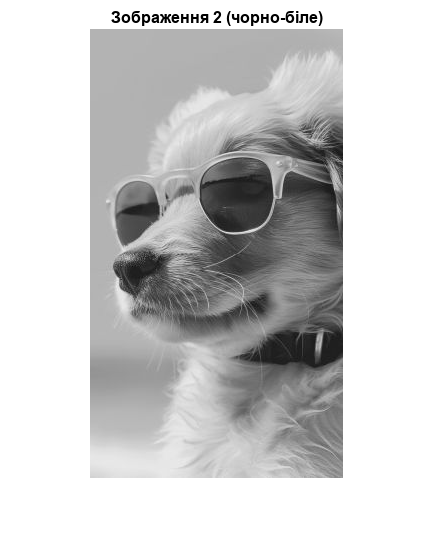

imshow(I2_gray); 
title('Зображення 2 (чорно-біле)');

I3_gray = I3

I3_gray = 256×256 uint8 matrix
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155

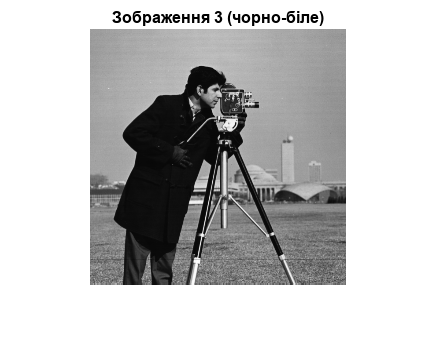

imshow(I3_gray); 
title('Зображення 3 (чорно-біле)');

% дискретне косинусне перетворення
J1 = dct2(I1_gray)

J1 = 1.0e+04 *

    3.0576   -0.2864    0.6321    0.0842    0.0740    0.1510   -0.1495   -0.0515    0.0229   -0.0789    0.0141    0.0564    0.0204    0.0166    0.0148    0.0113   -0.0134    0.0026   -0.0023   -0.0148   -0.0050   -0.0040    0.0061    0.0032   -0.0065    0.0090    0.0042    0.0001    0.0067    0.0064   -0.0117   -0.0043    0.0057   -0.0078   -0.0031    0.0145    0.0005    0.0016    0.0062   -0.0047    0.0056    0.0054   -0.0043   -0.0034   -0.0035   -0.0027   -0.0002   -0.0023    0.0018   -0.0007
    0.4277    0.2451   -0.0958   -0.0522    0.0128   -0.0399   -0.0006   -0.0034   -0.0118   -0.0088   -0.0168    0.0124    0.0363   -0.0303    0.0145    0.0095   -0.0318    0.0189    0.0096   -0.0184    0.0162   -0.0089   -0.0071    0.0079   -0.0115   -0.0030    0.0078   -0.0055   -0.0027    0.0046   -0.0077   -0.0034    0.0003   -0.0067   -0.0043    0.0060    0.0008   -0.0004    0.0013   -0.0031    0.0045    0.0060   -0.0053    0.0031    0.0030   -0.0035    0.0025    0.0031   

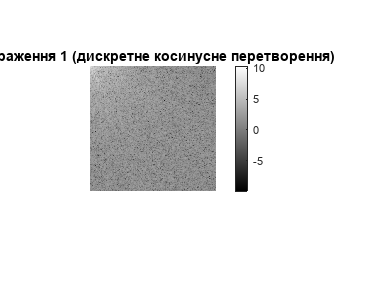

figure;
imshow(log(abs(J1)),[]), colorbar
title('Зображення 1 (дискретне косинусне перетворення)');

J2 = dct2(I2_gray)

J2 = 1.0e+04 *

    5.0920    0.6442   -0.0785   -0.0913    0.0231    0.2957    0.0781   -0.0315   -0.0179   -0.0541   -0.0268   -0.0069   -0.0324   -0.0049   -0.0024   -0.0226    0.0196   -0.0120    0.0016    0.0203    0.0061   -0.0046    0.0122   -0.0119    0.0223    0.0011   -0.0104    0.0065    0.0020    0.0072   -0.0028   -0.0022   -0.0184    0.0051   -0.0116    0.0039   -0.0008    0.0018    0.0028   -0.0019   -0.0034   -0.0010    0.0078    0.0031    0.0029   -0.0023   -0.0036    0.0065   -0.0040    0.0025
    0.0933   -0.2328    0.0953   -0.0153   -0.0608    0.0336    0.0253    0.0174    0.0084   -0.0038    0.0058   -0.0204   -0.0090    0.0130    0.0059   -0.0150    0.0048   -0.0127   -0.0111    0.0130   -0.0021    0.0017    0.0065    0.0039    0.0016    0.0036   -0.0160    0.0104   -0.0003    0.0004    0.0033   -0.0085    0.0010   -0.0000    0.0009   -0.0017   -0.0006    0.0015   -0.0024    0.0029   -0.0094    0.0074   -0.0020    0.0054   -0.0021    0.0020   -0.0014    0.0028   

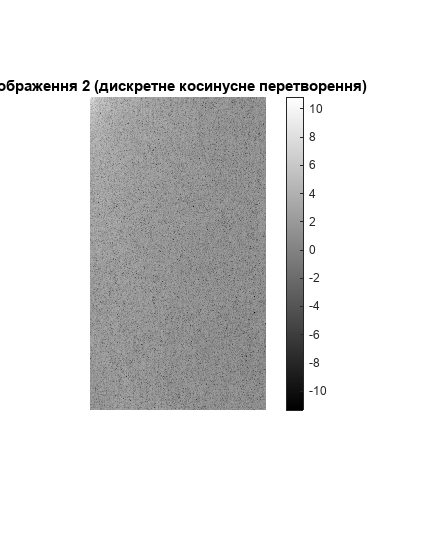

figure;
imshow(log(abs(J2)),[]), colorbar
title('Зображення 2 (дискретне косинусне перетворення)');

J3 = dct2(I3_gray)

J3 = 1.0e+04 *

    3.0393   -0.4226    0.2730    0.5372    0.2063    0.1076    0.0120   -0.0103   -0.0836   -0.0579   -0.0402   -0.0264   -0.0219   -0.0751   -0.0570    0.0385    0.0398   -0.0057    0.0317    0.0463    0.0062   -0.0250   -0.0054    0.0120   -0.0161   -0.0086    0.0016   -0.0256    0.0086    0.0226   -0.0153   -0.0188   -0.0065    0.0156    0.0050    0.0100    0.0131   -0.0013   -0.0143   -0.0026   -0.0070   -0.0149   -0.0106   -0.0024    0.0077    0.0158    0.0004   -0.0069    0.0080    0.0156
    0.5709    0.1649    0.1211   -0.0594   -0.2930   -0.1836    0.0038    0.0171    0.0198   -0.0104   -0.0315    0.0258    0.0746    0.0672    0.0244   -0.0068   -0.0095   -0.0118   -0.0282   -0.0222   -0.0223   -0.0106    0.0085   -0.0020    0.0040    0.0167    0.0046    0.0069    0.0031    0.0092   -0.0060   -0.0069    0.0262    0.0053   -0.0286   -0.0161    0.0045   -0.0074    0.0027    0.0147    0.0168    0.0116   -0.0000   -0.0013   -0.0039   -0.0134   -0.0052    0.0034   

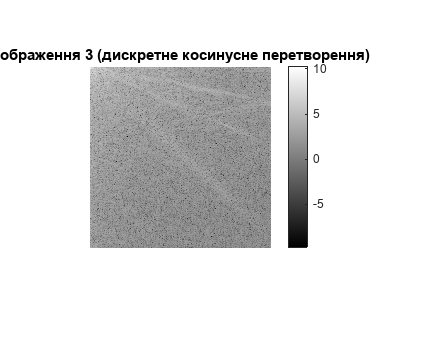

figure;
imshow(log(abs(J3)),[]), colorbar
title('Зображення 3 (дискретне косинусне перетворення)');

I1_return = idct2(J1)

I1_return =   206.0000  211.0000  216.0000  221.0000  225.0000  231.0000  237.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  241.0000  239.0000  237.0000  238.0000  237.0000  237.0000  237.0000  236.0000  236.0000  238.0000  241.0000  241.0000  241.0000  240.0000  240.0000  240.0000  241.0000  241.0000  242.0000  244.0000  243.0000  242.0000  242.0000  241.0000  240.0000  239.0000  238.0000  236.0000  235.0000  234.0000  234.0000  235.0000  236.0000  235.0000  234.0000  232.0000  232.0000
  208.0000  212.0000  217.0000  221.0000  226.0000  232.0000  237.0000  239.0000  241.0000  241.0000  241.0000  240.0000  241.0000  241.0000  239.0000  237.0000  236.0000  236.0000  237.0000  238.0000  237.0000  237.0000  238.0000  240.0000  240.0000  240.0000  239.0000  238.0000  239.0000  239.0000  240.0000  240.0000  242.0000  241.0000  240.0000  239.0000  239.0000  238.0000  237.0000  237.0000  236.0000  235.0000  234.0000  234.0000  234.0000  234.0000  233.0000  232.0000  231.0

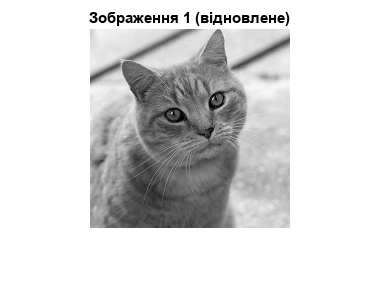

imshow(I1_return,[0 255])
title('Зображення 1 (відновлене)');

I2_return = idct2(J2)

I2_return =   179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000
  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0000  179.0

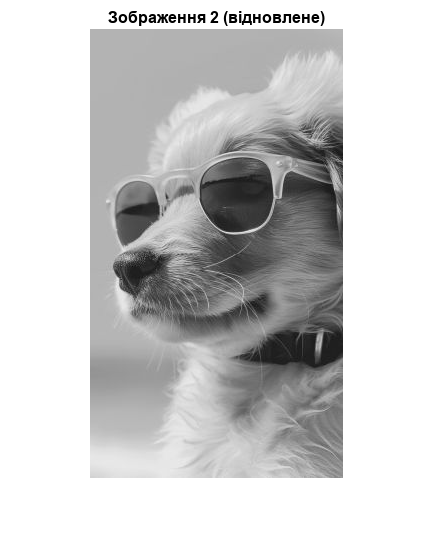

imshow(I2_return,[0 255])
title('Зображення 2 (відновлене)');

I3_return = idct2(J3)

I3_return =   156.0000  159.0000  158.0000  155.0000  158.0000  156.0000  159.0000  158.0000  157.0000  158.0000  158.0000  159.0000  160.0000  160.0000  160.0000  158.0000  163.0000  161.0000  162.0000  160.0000  164.0000  160.0000  165.0000  163.0000  161.0000  163.0000  161.0000  164.0000  165.0000  162.0000  161.0000  165.0000  165.0000  164.0000  166.0000  165.0000  164.0000  166.0000  167.0000  165.0000  165.0000  164.0000  170.0000  166.0000  167.0000  167.0000  170.0000  168.0000  169.0000  166.0000
  160.0000  154.0000  157.0000  158.0000  157.0000  159.0000  158.0000  158.0000  158.0000  160.0000  155.0000  156.0000  159.0000  158.0000  160.0000  157.0000  165.0000  159.0000  161.0000  158.0000  162.0000  162.0000  161.0000  163.0000  159.0000  162.0000  164.0000  163.0000  164.0000  165.0000  169.0000  164.0000  163.0000  165.0000  161.0000  163.0000  165.0000  168.0000  167.0000  165.0000  164.0000  163.0000  169.0000  169.0000  169.0000  170.0000  170.0000  169.0000  170.0

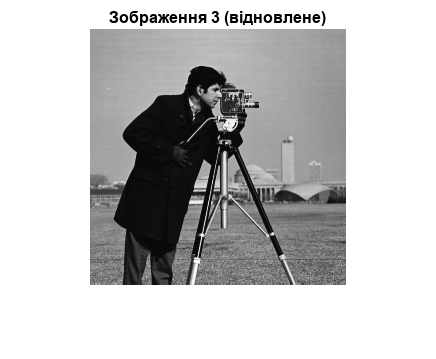

imshow(I3_return,[0 255])
title('Зображення 3 (відновлене)');

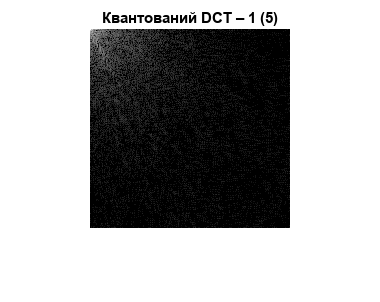

% квантування
N = 5; % крок квантування
J1q = N * round(J1 / N);
J2q = N * round(J2 / N);
J3q = N * round(J3 / N);
figure, imshow(log(abs(J1q)),[]), title('Квантований DCT – 1 (5)');

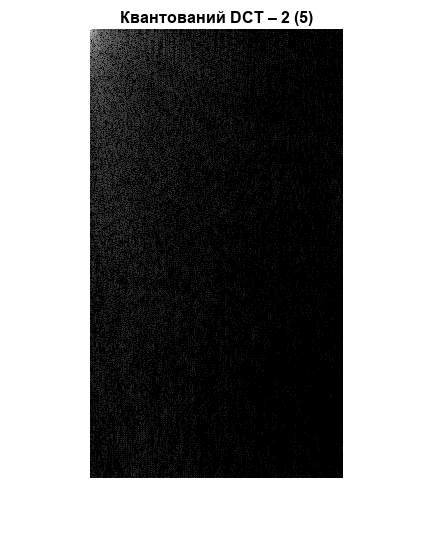

figure, imshow(log(abs(J2q)),[]), title('Квантований DCT – 2 (5)');

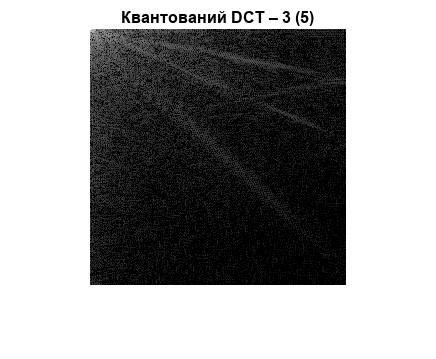

figure, imshow(log(abs(J3q)),[]), title('Квантований DCT – 3 (5)');

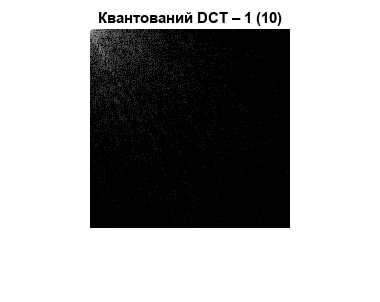

N = 10; % Крок квантування
J1q2 = N * round(J1 / N);
J2q2 = N * round(J2 / N);
J3q2 = N * round(J3 / N);
figure, imshow(log(abs(J1q2)),[]), title('Квантований DCT – 1 (10)');

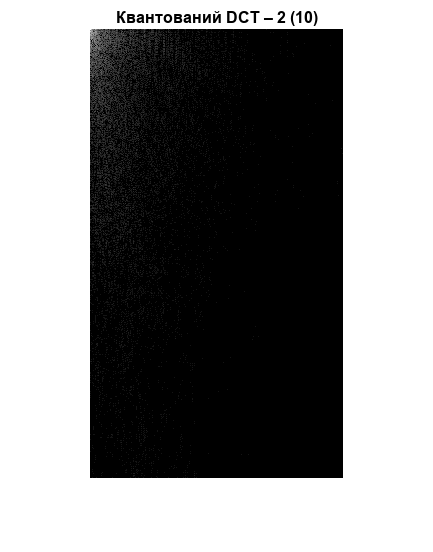

figure, imshow(log(abs(J2q2)),[]), title('Квантований DCT – 2 (10)');

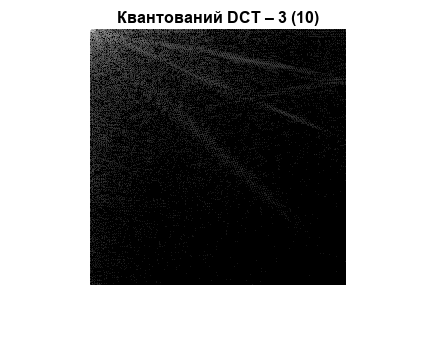

figure, imshow(log(abs(J3q2)),[]), title('Квантований DCT – 3 (10)');

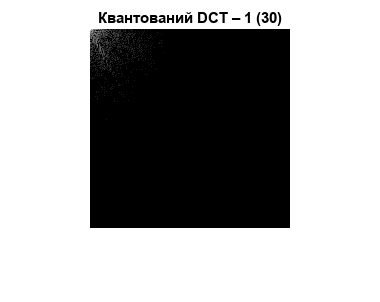

N = 30; % Крок квантування
J1q3 = N * round(J1 / N);
J2q3 = N * round(J2 / N);
J3q3 = N * round(J3 / N);
figure, imshow(log(abs(J1q3)),[]), title('Квантований DCT – 1 (30)');

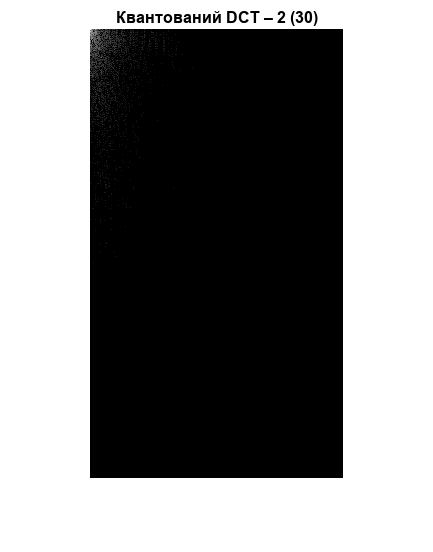

figure, imshow(log(abs(J2q3)),[]), title('Квантований DCT – 2 (30)');

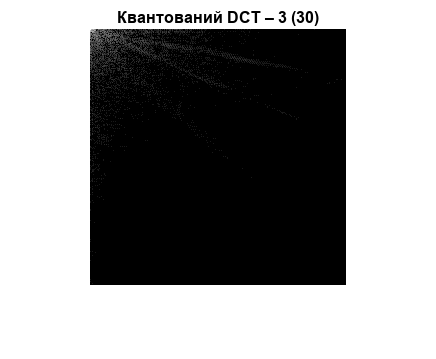

figure, imshow(log(abs(J3q3)),[]), title('Квантований DCT – 3 (30)');

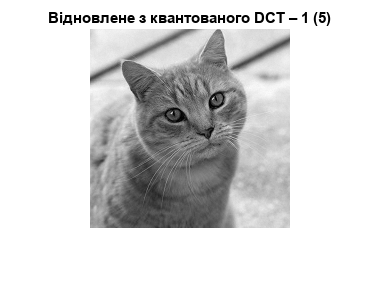

K1q = idct2(J1q);
K2q = idct2(J2q);
K3q = idct2(J3q);

figure, imshow(K1q,[0 255]), title('Відновлене з квантованого DCT – 1 (5)');

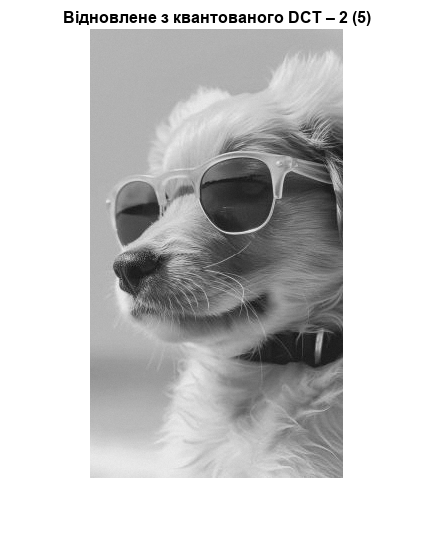

figure, imshow(K2q,[0 255]), title('Відновлене з квантованого DCT – 2 (5)');

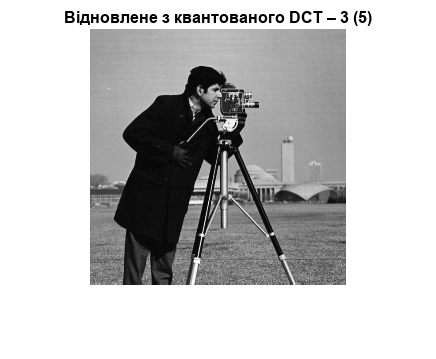

figure, imshow(K3q,[0 255]), title('Відновлене з квантованого DCT – 3 (5)');

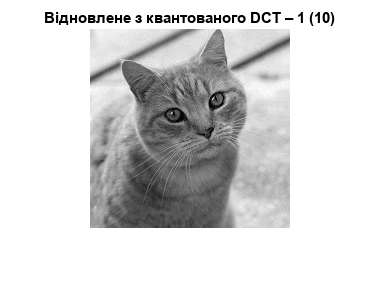

K1q2 = idct2(J1q2);
K2q2 = idct2(J2q2);
K3q2 = idct2(J3q2);

figure, imshow(K1q2,[0 255]), title('Відновлене з квантованого DCT – 1 (10)');

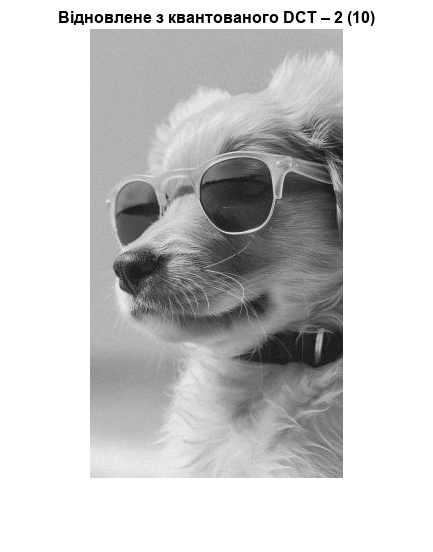

figure, imshow(K2q2,[0 255]), title('Відновлене з квантованого DCT – 2 (10)');

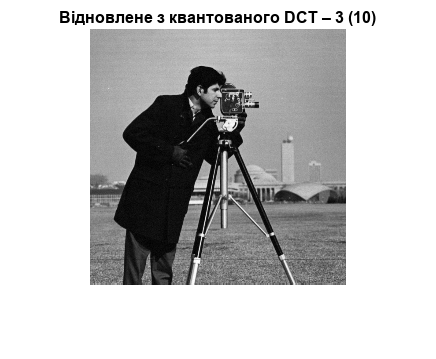

figure, imshow(K3q2,[0 255]), title('Відновлене з квантованого DCT – 3 (10)');

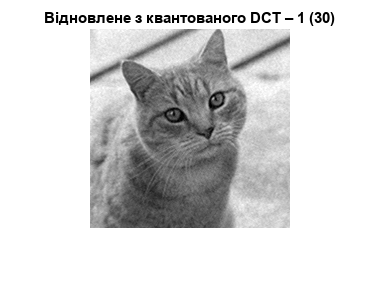

K1q3 = idct2(J1q3);
K2q3 = idct2(J2q3);
K3q3 = idct2(J3q3);

figure, imshow(K1q3,[0 255]), title('Відновлене з квантованого DCT – 1 (30)');

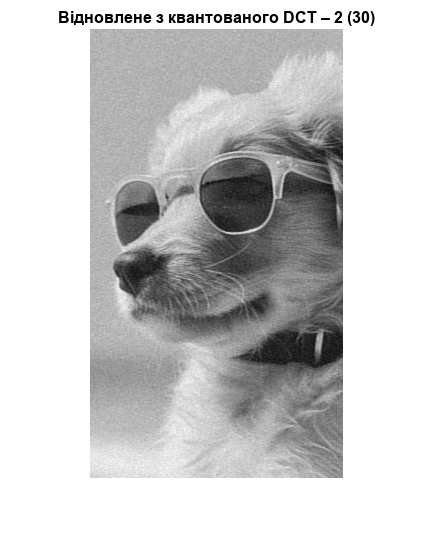

figure, imshow(K2q3,[0 255]), title('Відновлене з квантованого DCT – 2 (30)');

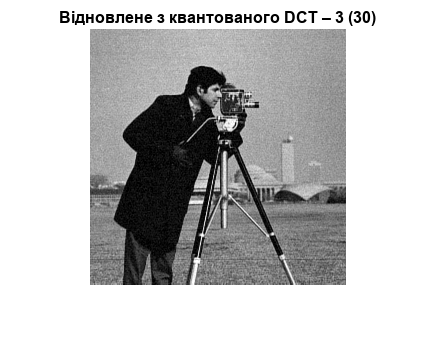

figure, imshow(K3q3,[0 255]), title('Відновлене з квантованого DCT – 3 (30)');

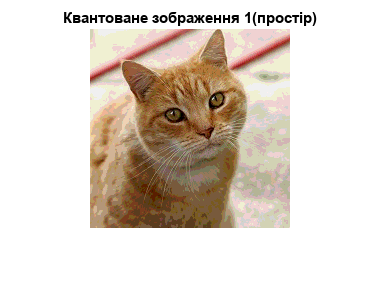

% квантування одразу 
n = 30;
Iq1_ = round(double(I1)/n)*n;
Iq2_ = round(double(I2)/n)*n;
Iq3_ = round(double(I3)/n)*n;

figure, imshow(uint8(Iq1_)), title('Квантоване зображення 1(простір)');

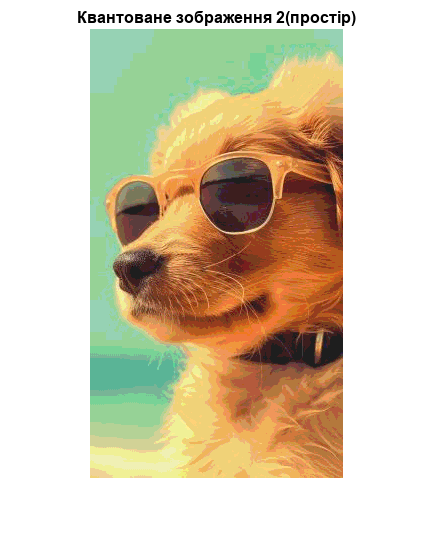

figure, imshow(uint8(Iq2_)), title('Квантоване зображення 2(простір)');

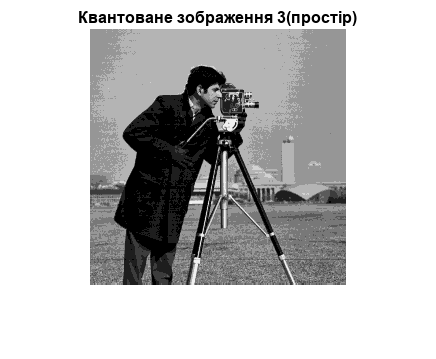

figure, imshow(uint8(Iq3_)), title('Квантоване зображення 3(простір)');